# Playing with bases

Bases are allow expressing vectors and tensors in the form of components that we can manipulate and operate with. In Anakin, orthonormal right-handed  bases are created with class `basis`.

As always, start by importing the Anakin framework into Matlab. Be sure to include Anakin's base directory before you run this line:

import anakin.*

## Object creation

We can think of the default basis as the canonical vector basis:

B = basis % default call

B = Basis with canonical rotation matrix:
     1     0     0
     0     1     0
     0     0     1


A new vector basis can be created by passing 3 vector objects, the components of such vectors in the canonical vector basis in row or column format, or the transformation matrix of the basis (where each column is the components of each vector in the canonical vector basis):

theta = 30*pi/180;
i1 = tensor([cos(theta),sin(theta),0]);
j1 = tensor([-sin(theta),cos(theta),0]);
k1 = tensor([0,0,1])

k1 = Vector with canonical components:
     0
     0
     1



B1 = basis(i1,j1,k1)

B1 = Basis with canonical rotation matrix:
    0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


B1 = basis([cos(theta),sin(theta),0],[-sin(theta),cos(theta),0],[0,0,1])

B1 = Basis with canonical rotation matrix:
    0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


B1 = basis([cos(theta);sin(theta);0],[-sin(theta);cos(theta);0],[0;0;1])

B1 = Basis with canonical rotation matrix:
    0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


B1 = basis([cos(theta),-sin(theta),0;
            sin(theta), cos(theta),0;
                     0,          0,1])

B1 = Basis with canonical rotation matrix:
    0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


One can also define a vector basis with respect to another one, by passing the latter as the last argument. Internally, the basis object stores only its change of basis matrix with respect to the canonical basis:

phi = 30*pi/180;
B0 = basis([1;0;0],[0;cos(phi);sin(phi)],[0;-sin(phi);cos(phi)]);

B1 = basis([cos(theta);sin(theta);0],[-sin(theta);cos(theta);0],[0;0;1],B0)

B1 = Basis with canonical rotation matrix:
    0.8660   -0.5000         0
    0.4330    0.7500   -0.5000
    0.2500    0.4330    0.8660


% Check: the change-of-basis matrix of B1 with respect to the canonical 
% basis must be equal to the following operation:
[1,         0,          0;
 0,cos(theta),-sin(theta);
 0,sin(theta), cos(theta)] * [cos(theta),-sin(theta),0;
                              sin(theta), cos(theta),0;
                              0,       0,            1]

ans =     0.8660   -0.5000         0
    0.4330    0.7500   -0.5000
    0.2500    0.4330    0.8660


For convenience, any object of basis or frame class can be passed as input. The result is converted to class basis:

S = frame; % a frame object, subclass of basis
B = basis(S); % converted to basis

## Basic functionality

To obtain the change-of-basis matrix of an existing basis with respect to another one, use the `matrix` method:

B1.matrix % matrix with respect to the canonical vector basis

ans =     0.8660   -0.5000         0
    0.4330    0.7500   -0.5000
    0.2500    0.4330    0.8660


B1.matrix(B0) % matrix with respect to B0

ans =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


The vectors **i**, **j**, **k** of the basis can be extracted with method `e`:

B1.e(1) 

ans = Vector with canonical components:
    0.8660
    0.4330
    0.2500


B1.e(2)

ans = Vector with canonical components:
   -0.5000
    0.7500
    0.4330


B1.e(3)

ans = Vector with canonical components:
         0
   -0.5000
    0.8660


Bases can be multiplied and divided. The result is a new basis with a change-of-basis matrix that results from multiplying or dividing their matrices. There are other useful methods that can be used:

B0 = basis([1;0;0],[0;cos(phi);sin(phi)],[0;-sin(phi);cos(phi)]);
B1 = basis([cos(theta);sin(theta);0],[-sin(theta);cos(theta);0],[0;0;1]);

B0*B1

ans = Basis with canonical rotation matrix:
    0.8660   -0.5000         0
    0.4330    0.7500   -0.5000
    0.2500    0.4330    0.8660


B0\B1

ans = Basis with canonical rotation matrix:
    0.8660   -0.5000         0
    0.4330    0.7500    0.5000
   -0.2500   -0.4330    0.8660


B0/B1

ans = Basis with canonical rotation matrix:
    0.8660    0.5000         0
   -0.4330    0.7500   -0.5000
   -0.2500    0.4330    0.8660


B0^(-1)

ans = Basis with canonical rotation matrix:
    1.0000         0         0
         0    0.8660    0.5000
         0   -0.5000    0.8660


inv(B0)

ans = Basis with canonical rotation matrix:
    1.0000         0         0
         0    0.8660    0.5000
         0   -0.5000    0.8660


B0'

ans = Basis with canonical rotation matrix:
    1.0000         0         0
         0    0.8660    0.5000
         0   -0.5000    0.8660


B0.'

ans = Basis with canonical rotation matrix:
    1.0000         0         0
         0    0.8660    0.5000
         0   -0.5000    0.8660



B0 == B1 % compare two bases

ans = logical
   0


B0 ~= B1

ans = logical
   1


By default, the `basis` class creator does not check if the basis is orthonormal and right handed, but some funcionality of Anakin may require these properties. To check, use the logical methods `isorthonormal` and `isrighthanded`:

isorthonormal(B0) % returns 1 or 0, depending on the property being true 

ans = logical
   1


isrighthanded(B0)

ans = logical
   1


There are utilities to create bases through simple rotations. These are useful to define a new basis from its Euler angles:

yaw = 20*pi/180;
pitch = 30*pi/180;
roll = 40*pi/180;

B = basis; % canonical vector basis
B1 = B.rotatez(yaw)

B1 = Basis with canonical rotation matrix:
    0.9397   -0.3420         0
    0.3420    0.9397         0
         0         0    1.0000


B2 = B1.rotatey(pitch)

B2 = Basis with canonical rotation matrix:
    0.8138   -0.3420    0.4698
    0.2962    0.9397    0.1710
   -0.5000         0    0.8660


B3 = B2.rotatex(roll)

B3 = Basis with canonical rotation matrix:
    0.8138    0.0400    0.5798
    0.2962    0.8298   -0.4730
   -0.5000    0.5567    0.6634


And utilities to get the unit vector and angle of rotation, the quaternions, and the Euler angles of the matrix of a basis (note: you can also create vector bases from quaternions, or from an axis-angle pair):

axis = B1.rotaxis

axis = Vector with canonical components:
     0
     0
     1


angle = B1.rotangle; angle*180/pi

ans = 20.0000

q = B3.quaternions

q =     0.2831
    0.2969
    0.0704
    0.9093


B3.euler([3,2,1],B)*180/pi

ans =    20.0000   30.0000   40.0000



B4 = basis(q)

B4 = Basis with canonical rotation matrix:
    0.8138    0.0400    0.5798
    0.2962    0.8298   -0.4730
   -0.5000    0.5567    0.6634


B5 = basis(axis,angle)

B5 = Basis with canonical rotation matrix:
    0.9397   -0.3420         0
    0.3420    0.9397         0
         0         0    1.0000


Finally, a numeric vector basis can be plotted using `plot`:

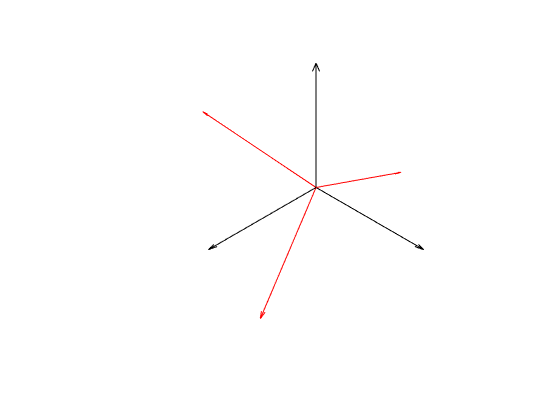

ax = axes('DataAspectRatio',[1,1,1]);
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
view([1,1,1]);

B.plot;
B3.plot('color','r'); % pass quiver3 plotting arguments to change color, style, etc.

## Symbolic vector bases

Symbolic vector bases have additional functionality (running this requires the Symbolic Math Toolbox installed):

syms t theta(t) phi(t); % declare symbolic variables
assume([in(t, 'real'), in(theta(t), 'real'), in(phi(t), 'real')]); 

B0 = basis([1;0;0],[0;cos(phi);sin(phi)],[0;-sin(phi);cos(phi)]) % a rotating vector basis

B0 = Basis with canonical rotation matrix:
[ 1,           0,            0]
[ 0, cos(phi(t)), -sin(phi(t))]
[ 0, sin(phi(t)),  cos(phi(t))]
 

B1 = basis([cos(theta);sin(theta);0],[-sin(theta);cos(theta);0],[0;0;1])

B1 = Basis with canonical rotation matrix:
[ cos(theta(t)), -sin(theta(t)), 0]
[ sin(theta(t)),  cos(theta(t)), 0]
[             0,              0, 1]
 

One may compute angular velocity and angular acceleration vectors of the vector basis with respect to another basis:

B1.omega % with respect to canonical vector basis

ans = Vector with canonical components:
                 0
                 0
 diff(theta(t), t)
 

B1.omega(B0) % with respect to B0

ans = Vector with canonical components:
  -diff(phi(t), t)
                 0
 diff(theta(t), t)
 


B1.alpha

ans = Vector with canonical components:
                    0
                    0
 diff(theta(t), t, t)
 

To particularize a symbolic vector basis at particular values of its parameters, one may use `subs`, by specifying them in a list:

B1.subs({theta},{pi/6}) % replace theta with pi/6

ans = Basis with canonical rotation matrix:
    0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000
